Problema de Fermat-Weber

Analisis Aplicado

ITAM

2 de febrero de 2023

load Puntos
[n,m] = size(A);
vc = zeros(3,1);
for j = 1:m
    v = A(:,j);
    vc = vc + v;
    plot3(v(1),v(2),v(3),'dr','LineWidth',3)
    hold on
end
vc = vc/m;

plot3(vc(1),vc(2),vc(3),'sk','LineWidth',3)
title('Problema de Fermat-Weber')
hold on

fname = 'ferweb';
x0 = 20*randn(3,1);

Codigo de maximo descenso

[xf1, j1] = desmax(fname,x0);
[xf2, j2] = desnewton(fname,x0);

 1 179.28704577 
 2 65.16690985 
 3 10.28026275 
 4 0.20818089 
 5 0.00011341 
 6 0.00011328 
 7 0.00011299 
 8 0.00011322 
 9 0.00011281 
10 0.00011276 
11 0.00011271 
12 0.00011242 
13 0.00011216 
14 0.00011224 
15 0.00011192 
16 0.00011193 
17 0.00011181 
18 0.00011198 
19 0.00011155 
20 0.00011145 
21 0.00011156 
22 0.00011132 
23 0.00011119 
24 0.00011110 
25 0.00011089 
26 0.00011084 
27 0.00011070 
28 0.00011072 
29 0.00011074 
30 0.00011065 
31 0.00011063 
32 0.00011038 
33 0.00011021 
34 0.00010990 
35 0.00010997 
36 0.00010986 
37 0.00010986 
38 0.00010973 
39 0.00010934 
40 0.00010945 
41 0.00010919 
42 0.00010904 
43 0.00010895 
44 0.00010866 
45 0.00010880 
46 0.00010835 
47 0.00010867 
48 0.00010840 
49 0.00010827 
50 0.00010823 
51 0.00010813 
52 0.00010792 
53 0.00010775 
54 0.00010775 
55 0.00010766 
56 0.00010764 
57 0.00010724 
58 0.00010734 
59 0.00010736 
60 0.00010710 
61 0.00010697 
62 0.00010662 
63 0.00010665 
64 0.00010659 
65 0.00010637 
66 0.00010635 
67 0.0

sol = [xf1 xf2 vc]

sol =     0.8121    0.8121    0.7134
   -0.4903   -0.4903   -1.5786
   -0.0854   -0.0854    1.8888



iter = [j1 j2]

iter =    100   100


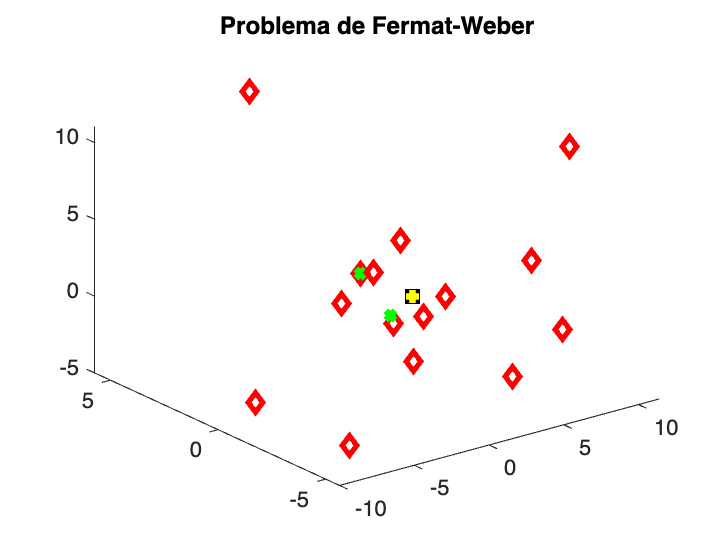

plot3(xf1(1), xf1(2), xf1(3),'xg','LineWidth',3)
hold on 
plot3(vc(1), vc(2), vc(3),'+y','LineWidth',3)
hold on 

fopt = feval(fname, xf1);
fvc = feval(fname, vc);

vf = [fopt fvc]

vf = 1.0e+03 *

    7.7270    8.0920



g = gradiente(fname, xf1);
ng = norm(g)

ng = 6.6463e-05